**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221**

**Q1. Use Matlab's neural network tool box to create a 3 class decision classifier for the 3 class data generated in Exercise 1.**

clear;
clc;

% loading the variables from the exercise 1
a = load("ex1.mat")

a = struct with fields:
          Da: [3×3 double]
          Db: [3×3 double]
          Dc: [3×3 double]
           K: 1000
          Va: [3×3 double]
          Vb: [3×3 double]
          Vc: [3×3 double]
           W: [1000×3 double]
         ans: [-2.0000 -5.0000 -5]
    filename: 'ex1.mat'
         muA: [3×1 double]
         muB: [3×1 double]
         muC: [3×1 double]
         muT: [3×1 double]
      sigmaA: [3×3 double]
      sigmaB: [3×3 double]
      sigmaC: [3×3 double]
      sigmaT: [3×3 double]
    testdata: [50×3 double]
           y: [1000×3 double]
           z: [1000×3 double]


%Since a priori class probabilities are equal.
priorA = 1/3;
priorB = 1/3;
priorC = 1/3;

**Input Vector:** corresponds to the independent features that need to be classified i.e. data points that need to be classified A, B and C in our case.

inputVector = horzcat(a.y', a.z',a.W')

inputVector =    -2.2127   -1.3820   -0.7868    1.2261    0.4952   -1.4164   -3.3674    0.7175    2.3944   -0.9580    1.6896    5.2320   -1.1619   -6.5251    1.0880   -2.9826   -2.0270    1.4307    1.3960   -0.1224   -2.2141    4.1305   -2.3686   -3.3158   -3.3048   -1.9041   -1.2653   -5.5240   -1.0970   -3.1594    0.1152   -2.7072    3.1286   -4.8848   -0.5547   -0.3689    0.3876   -3.2732    1.8704    0.5337    4.9182   -0.8032   -3.2803    6.6613    0.8779    0.0045    1.0392   -4.7136    0.5060    0.9628
    5.6775    7.2013    3.0579    3.2276    3.4002    6.4188    3.2100    4.1200    6.6636    2.8548    6.5055    6.4275    6.3974    3.8046    6.1412    1.7486    3.7355    2.8548   -0.1673    2.0825    7.5688    4.4228    4.9184   -0.7536    4.6185    4.3594    5.2093    3.7239    5.0829    6.6086    2.9246    3.4266    5.1092    6.0277    6.6620    1.3668    4.3124    6.6992    1.7320    4.9207    6.7317    2.8087    1.7246    3.9237    1.3013    7.8677    0.2525    2.4491    3

% One hot encoding the class labels
trueclassindices = [ 1 2 3];
One_hot_encoded = full(ind2vec(trueclassindices,3))

One_hot_encoded =      1     0     0
     0     1     0
     0     0     1


% repeating the class label 1000 times
label_A = repmat(One_hot_encoded(1,:), a.K,1);
label_B = repmat(One_hot_encoded(2,:),a.K,1);
label_C = repmat(One_hot_encoded(3,:), a.K,1);

% Target_label corresponds to the labels of classes A,B and C
target_label = horzcat(label_A',label_B',label_C');

**Neural Network Classifier**

inputs = inputVector;
targets = target_label;
hiddenLayerSize = 50;
net = patternnet(hiddenLayerSize);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
rng(1)
[net,tr] = train(net,inputs,targets);
view(net)

**Generating random points and applying the neural network to classify the points**

points= vol3D([-15 20 -15 20 -15 20],200);
%% Results corresponds to the output classification label predicted by
% the trained neural network for randomly generated .
results = net(points');
g = results'

g =     0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000


**Q2. Plotting the decision boundary created by trained neural network**

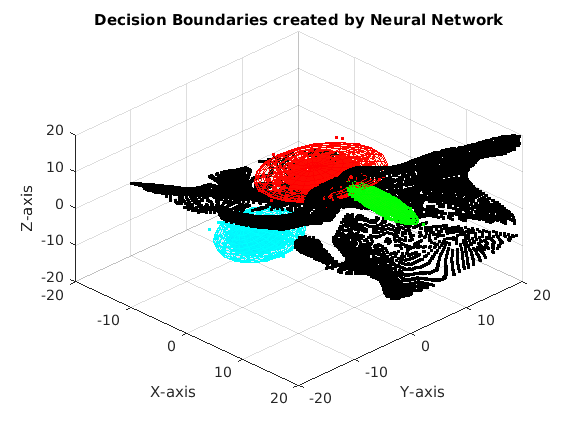

epsilon_NN_1 = 1e-1;
epsilon_NN_2 = 1e-2; 
decisionbound1 =  abs(g(:, 1) - g(:, 2));
decisionbound2 =  abs(g(:, 2) - g(:, 3));
decisionbound3 =  abs(g(:, 1) - g(:, 3));

ind_boundary_1 = find(abs(g(:, 1)) <= epsilon_NN_1 & decisionbound2 < epsilon_NN_2);
ind_boundary_2 = find(abs(g(:, 2)) <= epsilon_NN_1 & decisionbound3 < epsilon_NN_2);
ind_boundary_3 = find(abs(g(:, 3)) <= epsilon_NN_1 & decisionbound1 < epsilon_NN_2);    
boundary_1 = points(ind_boundary_1,:);
boundary_2 = points(ind_boundary_2,:);
boundary_3 = points(ind_boundary_3,:);


% plotting the decision boundary boundary created by neural network
Classes(a.y,a.muA,a.sigmaA,a.z,a.muB,a.sigmaB,a.W,a.muC,a.sigmaC,boundary_1,boundary_2,boundary_3,[0 0 0])
title('Decision Boundaries created by Neural Network')

**Q2 Discussion **

**Discuss the "correctness" of neural network boundaries versus Bayesian boundaries.**

The bayesian classifier is the optimal solution available to create the decision boundaries for classifying the given dataset.This is attributed to the fact that the bayesian classifier considers the probability distribution and therefore, considers an infinite amount of dataset for generating the classification. Hence, decision boundaries plotted by bayesian classifer can be considered the correct decision boundaries.

In contrast to bayesian classifier, neural network is exposed to only a subset of the dataset and infers the decision boundaries in proximity to the provided dataset. Hence, does not cover the infinite amount of dataset for providing the decision boundaries. This is evident from the plot above, the decision boundaries plotted by neural network classifier are very different to that of the bayesian decision boundaries plotted in Exercise 2. 

Therefore, by comparing the "correct" bayesian decision boundaries of Exercise 2 with the decision boundaries plotted by neural network, we can say that decision boundaries plotted by neural network are not 100% correct. The neural network can provide correct decision boundaries if provided with infinite amount of data. However, that's an impossible requirement to fulfill.

**Q3 Evaluating performance of Neural Network Classifer**

%nprtool

%% Outputs corresponds to the output classification information predicted by
% the trained neural network for the data that was used for training the model.
outputs = net(inputs);

% Training Error metrics provided by the NPR tool
performance = perform(net, target_label, outputs);
disp(performance)

    0.0044



The below comments capture the approach used by the nprtool for evaluating the performance of the network. The performance tool calculates the classification accuracy to report neural network's error. 

The accuracy score calculation method used by MATLAB is correct, however, reporting the performance of neural network just on the basis of accuracy score is not 100% correct. In general, classification accuracy alone is not enough to make a decision about whether or not the trained model will serve our purpose. As the classification accuracy can be misleading.  For example, in case of predicting recurrence of breast cancer from the provided data, we may want to be extra cautious about the False Negatives could be highly detrimental for the society. So in this case, evaluating the performance error of the classifier based only on the number of correct predictions made is not enough and we need to consider the other parameters such as precision, recall and F1 score for evaluation the performance of the classifier.

Precision is the number of True positives divided by the number of True Positives and False Positives. A low precision indicates higher number of false positives. 

Recall is the number of True Positives divided by the number of True Positives and the number of False Negatives. It can be said as the measure of classifier completeness. A low recall indicates higher number of false positives.

F1 Score indicates the balance between the precision and recall.

% performance = perform(net,t,y)
% tind = vec2ind(t);
% yind = vec2ind(y);
% percentErrors = sum(tind ~= yind)/numel(tind);

**Functions used**

function [] = ellipsoid_plot(mu,sigma,edge_color)
[V,D] = eigs(sigma);
std = sqrt(diag(D));

% obtaining position values using ellipsoid function, the ellipsoid
% function uses one, two and three standard deviation from the mean
[x1,y1,z1] = ellipsoid(0,0,0,std(1),std(2),std(3));
[x2,y2,z2] = ellipsoid(0,0,0,2*std(1),2*std(2),2*std(3));
[x3,y3,z3] = ellipsoid(0,0,0,3*std(1),3*std(2),3*std(3));    


% adjusting the position values of all the three different standard
% deviations

% plotting concentric ellipsoid 1 with one standard deviation

dim = [x1(:) y1(:) z1(:)]'; 
dim = V*dim + mu; % adjusting the mean
x1 = reshape(dim(1,:), size(x1));
y1 = reshape(dim(2,:), size(y1));
z1 = reshape(dim(3,:), size(z1));


surf(x1,y1,z1,'FaceAlpha',0.05,'EdgeColor',edge_color);

% plotting concentric ellipsoid 2 with two standard deviation
dim = [x2(:) y2(:) z2(:)]';
dim = V*dim + mu;
x2 = reshape(dim(1,:), size(x2));
y2 = reshape(dim(2,:), size(y2));
z2 = reshape(dim(3,:), size(z2));


surf(x2,y2,z2,'FaceAlpha',0.05,'EdgeColor',edge_color);

% plotting concentric ellipsoid 3 with three standard deviation
dim = [x3(:) y3(:) z3(:)]';
dim = V*dim + mu;
x3 = reshape(dim(1,:), size(x3));
y3 = reshape(dim(2,:), size(y3));
z3 = reshape(dim(3,:), size(z3));


surf(x3,y3,z3,'FaceAlpha',0.05,'EdgeColor',edge_color);
end

function [] = Classes(randomClassASamples,muClassA,sigmaClassA,randomClassBSamples,muClassB,sigmaClassB,randomClassCSamples,muClassC,sigmaClassC,boundary_1,boundary_2,boundary_3, color)
    
     ellipsoid_plot(muClassA,sigmaClassA,[1 0 0])
     hold on
     ellipsoid_plot(muClassB,sigmaClassB,[0 1 0])
     ellipsoid_plot(muClassC,sigmaClassC,[0 1 1])
    
    scatter3(randomClassASamples(:,1),randomClassASamples(:,2),randomClassASamples(:,3),'r.')
    scatter3(randomClassBSamples(:,1),randomClassBSamples(:,2),randomClassBSamples(:,3),'g.')
    scatter3(randomClassCSamples(:,1),randomClassCSamples(:,2),randomClassCSamples(:,3),'c.')
    plot3(boundary_1(:,1),boundary_1(:,2),boundary_1(:,3),'Marker',".","LineStyle","none","Color",color)
    plot3(boundary_2(:,1),boundary_2(:,2),boundary_2(:,3),'Marker',".","LineStyle","none","Color",color)
    plot3(boundary_3(:,1),boundary_3(:,2),boundary_3(:,3),'Marker',".","LineStyle","none","Color",color)
    hold off
    xlabel('X-axis')
    ylabel('Y-axis')
    zlabel('Z-axis')
    view([45 45])
end

function V = vol3D(Vaxis,Num)
% Build 3D volume of regular grid points 

    NV = Num;
    
    if length(Vaxis) == 2
        Vaxis = [Vaxis Vaxis Vaxis];
    end
    
    min_a = Vaxis(1);
    max_a = Vaxis(2);
    res = (max_a - min_a) / (NV - 1);
    %r = min_a: res: max_a;
    %r = r(:);
    rx = [Vaxis(1):(Vaxis(2) - Vaxis(1)) / (NV-1):Vaxis(2)]';
    ry = [Vaxis(3):(Vaxis(4) - Vaxis(3)) / (NV-1):Vaxis(4)]';
    rz = [Vaxis(5):(Vaxis(6) - Vaxis(5)) / (NV-1):Vaxis(6)]';
    x = zeros(3, length(rz)^3);
    k = 1;
    j = 1;
    
    for i = 1:length(rz):length(x)
        x(3, (i - 1) + (1: length(rz))) = rz;
        x(2, (i - 1) + (1: length(rz))) = ry(k) * ones(1, length(rz));
        x(1, (i - 1) + (1: length(rz))) = rx(j) * ones(1, length(rz));
        k = k + 1;
        if k > length(rz)
            k = 1;
            j = j + 1;
        end
    end
    x = x';
    V = x;

end